# Universal function approximation using neural networks

## Activation functions

x = -8:0.1:8;

Sigmoid

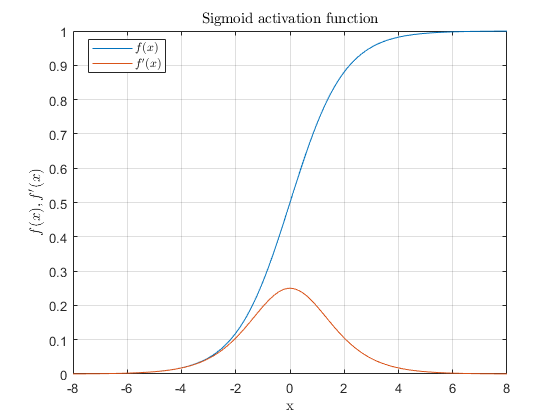

figure,
plot(x, sigmoid(x)); grid; hold on;
plot(x, sigmoid_derivative(x))
title("Sigmoid activation function", "Interpreter","latex")
xlabel("x", "Interpreter","latex")
ylabel("$f(x), f'(x)$", "Interpreter","latex")
legend("$f(x)$", "$f'(x)$", "interpreter", "latex", "Location","best");

Hyperbolic tangent

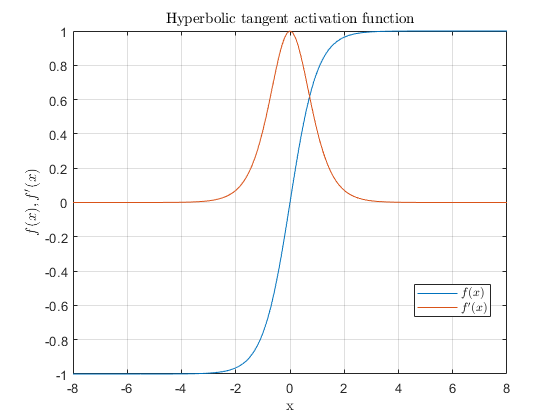

figure,
plot(x, tanh(x)); grid; hold on;
plot(x, tanh_derivative(x))
title("Hyperbolic tangent activation function", "Interpreter","latex")
xlabel("x", "Interpreter","latex")
ylabel("$f(x), f'(x)$", "Interpreter","latex")
legend("$f(x)$", "$f'(x)$", "interpreter", "latex", "Location","best");

## XOR problem using neural networks

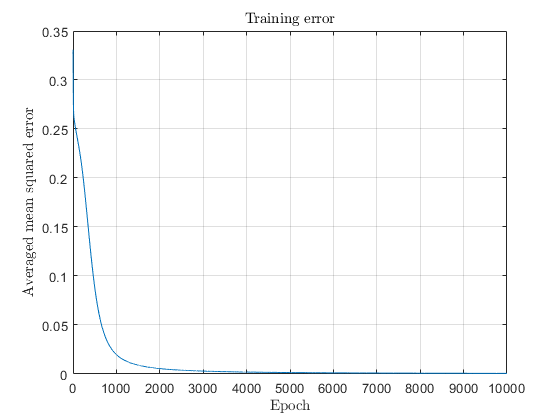

learning_rate = 0.1;

dense_layer = Dense(2, 5, "AllowBias", true, "LearningRate", learning_rate, "Momentum", 0.1);
dense_layer_activation = Activation(@sigmoid, @sigmoid_derivative);
output_layer = Dense(5, 1, "AllowBias", true, "LearningRate", learning_rate, "Momentum", 0.1);
output_layer_activation = Activation(@sigmoid, @sigmoid_derivative);

x = [0 1 0 1; 0 0 1 1];
y = [0 1 1 0];

number_of_epochs = 10000;
training_loss = zeros(number_of_epochs, 1);

for j = 1:number_of_epochs
    loss = 0;
    for i = 1:length(y)
        % inferece
        [y_hat, dense_layer] = dense_layer.forward(x(:, i));
        [y_hat, dense_layer_activation] = dense_layer_activation.forward(y_hat);
        [y_hat, output_layer] = output_layer.forward(y_hat);
        [y_hat, output_layer_activation] = output_layer_activation.forward(y_hat);
        
        loss = loss + mean_squared_error(y(i), y_hat);
        
        % back propagation
        [gradient, output_layer_activation] = output_layer_activation.backward( ...
            mean_squared_error_derivative(y(i), y_hat));
        [gradient, output_layer] = output_layer.backward(gradient);
        [gradient, dense_layer_activation] = dense_layer_activation.backward(gradient);
        [~, dense_layer] = dense_layer.backward(gradient);
    end
    training_loss(j) = loss/length(y);
end

figure, 
plot(training_loss); grid;
title("Training error", "Interpreter","latex");
ylabel("Averaged mean squared error", "Interpreter","latex");
xlabel("Epoch", "Interpreter","latex");

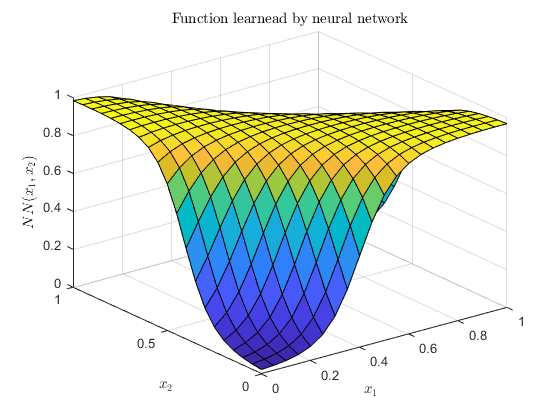


x = 0:0.05:1;
[X, Y] = meshgrid(x, x);
out = zeros(size(X));

[number_of_rows, number_of_culoms] = size(X);
for i = 1:number_of_rows
    for j = 1:number_of_culoms
        [y_hat, dense_layer] = dense_layer.forward([X(i, j) Y(i, j)]');
        [y_hat, dense_layer_activation] = dense_layer_activation.forward(y_hat);
        [y_hat, output_layer] = output_layer.forward(y_hat);
        [y_hat, output_layer_activation] = output_layer_activation.forward(y_hat);
        out(i, j) = y_hat;
    end
end

figure, 
surf(X, Y, out);
title("Function learnead by neural network", "Interpreter","latex");
xlabel("$x_1$", "Interpreter","latex");
ylabel("$x_2$", "Interpreter","latex");
zlabel("$NN(x_1,x_2)$", "Interpreter","latex");

## Function Approximation using neural networks

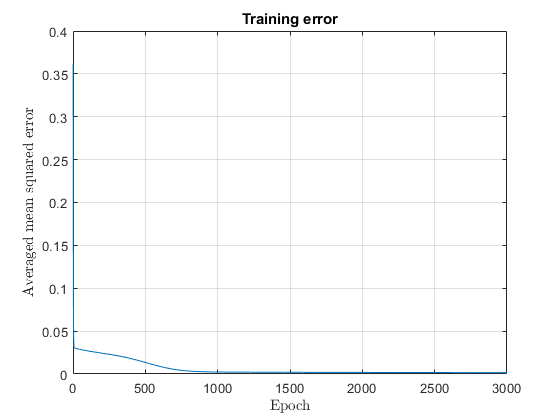

x = -1:0.01:1;
y = x.^3;
y = y/max(abs(y));

learning_rate = 0.001;
dense_layer = Dense(1, 6, "AllowBias", false, "LearningRate", learning_rate, "Momentum", 0.9);
dense_layer_activation = Activation(@tanh, @tanh_derivative);
output_layer = Dense(6, 1, "AllowBias", false, "LearningRate", learning_rate, "Momentum", 0.9);

number_of_epochs = 3000;
training_loss = zeros(number_of_epochs, 1);

for j = 1:number_of_epochs
    loss = 0;
    for i = 1:length(x)
        % inference
        [y_hat, dense_layer] = dense_layer.forward(x(i));
        [y_hat, dense_layer_activation] = dense_layer_activation.forward(y_hat);
        [y_hat, output_layer] = output_layer.forward(y_hat);
        
        loss = loss + mean_squared_error(y(i), y_hat);
        if isnan(y_hat)
            %disp(i)
        end
        
        % back propagation
        [gradient, output_layer] = output_layer.backward( ...
            mean_squared_error_derivative(y(i), y_hat));
        [gradient, dense_layer_activation] = dense_layer_activation.backward(gradient);
        [~, dense_layer] = dense_layer.backward(gradient);    
    end
    
    training_loss(j) = loss/length(x);
    % disp("Epoch: "+j+"/"+number_of_epochs+", loss: "+training_loss(j));
end

figure, 
plot(training_loss); grid;
title("Training error");
xlabel("Epoch", "Interpreter","latex");
ylabel("Averaged mean squared error", "Interpreter","latex");

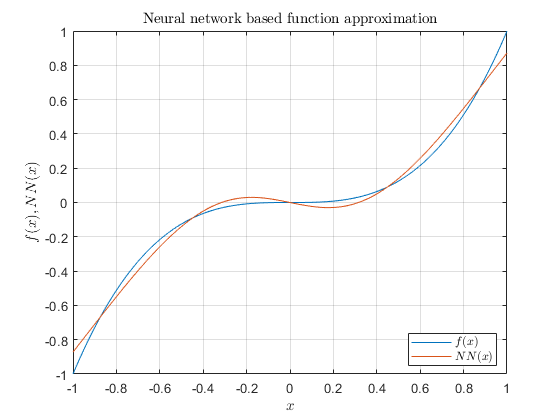


out = zeros(size(x));
for i = 1:length(x)
    [y_hat, dense_layer] = dense_layer.forward(x(i));
    [y_hat, dense_layer_activation] = dense_layer_activation.forward(y_hat);
    [y_hat, output_layer] = output_layer.forward(y_hat);
    out(i) = y_hat;
end

figure, 
plot(x, y); grid; hold on;
plot(x, out);
title("Neural network based function approximation", "Interpreter","latex");
xlabel("$x$", "Interpreter","latex");
ylabel("$f(x), NN(x)$", "Interpreter","latex");
legend("$f(x)$", "$NN(x)$", "Interpreter", "latex", "Location", "best");

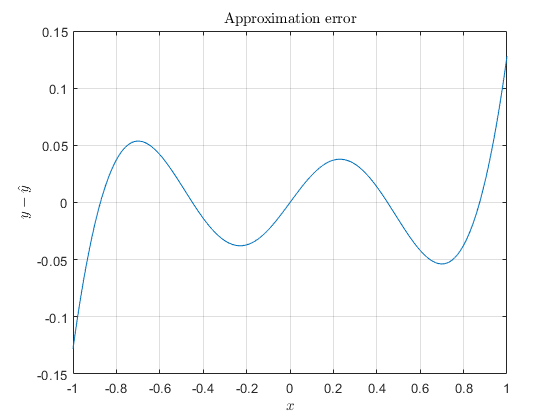


figure,
plot(x, y - out); grid; hold on;
title("Approximation error", "Interpreter","latex");
xlabel("$x$", "Interpreter", "latex");
ylabel("$y - \hat{y}$", "Interpreter", "latex");

function y = sigmoid(x)
    y = 1./(1 + exp(-x));
end

function y = sigmoid_derivative(x)
    y = sigmoid(x).*(1 - sigmoid(x));
end

function y = tanh(x)
    y = (exp(x) - exp(-x))./(exp(x) + exp(-x));
end

function y = tanh_derivative(x)
    y = (1 - tanh(x).^2);
end

function e = mean_squared_error(y, y_hat)
    e = sum((y - y_hat).^2)/length(y);
end

function e = mean_squared_error_derivative(y, y_hat)
    e = (2/length(y))*(y_hat' - y');
end